# Q1

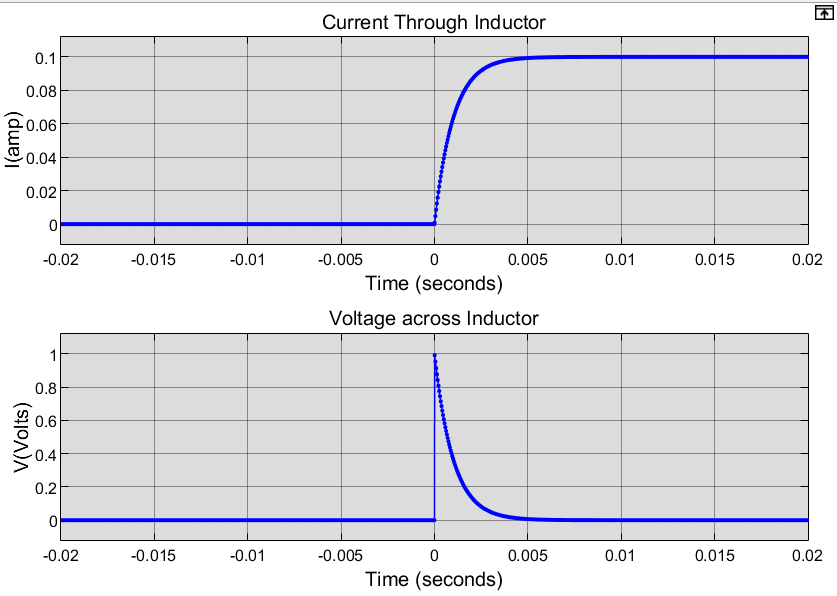

Time constant of the circuit is equal to $\frac{L}{R} = \frac{1mH}{10\Omega} = 10^{-3}s$ 

% a
% stimulation done on part1.slx
% The plot shows the current and voltage across the inductor vs time.


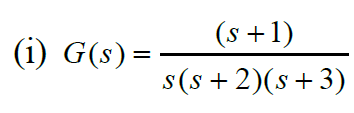

% b (i)
% zeros = [-1] 
% poles = [0,-2,-3] 
% gain = 1

tf1=tf([1,1],[1,5,6,0])

tf1 =
 
        s + 1
  -----------------
  s^3 + 5 s^2 + 6 s
 
Continuous-time transfer function.



zpk1=zpk(-1,[0,-2,-3],1)

zpk1 =
 
      (s+1)
  -------------
  s (s+2) (s+3)
 
Continuous-time zero/pole/gain model.



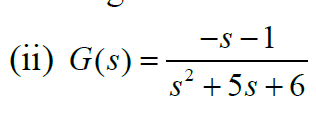

tf2=tf([-1,-1],[1,5,6])

tf2 =
 
     -s - 1
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.



zpk2=zpk(-1,[-2,-3],-1)

zpk2 =
 
    - (s+1)
  -----------
  (s+2) (s+3)
 
Continuous-time zero/pole/gain model.



% c
[A1, B1, C1, D1]=tf2ss([1,1],[1,5,6,0])

A1 =     -5    -6     0
     1     0     0
     0     1     0


B1 =      1
     0
     0


C1 =      0     1     1


D1 = 0

[A2,B2,C2,D2]=tf2ss([-1,-1],[1,5,6])

A2 =     -5    -6
     1     0


B2 =      1
     0


C2 =     -1    -1


D2 = 0

% time constant =L/R = 0.01/0.1 = 0.001 = 1ms
% set time is taken 10*time constant =0.01 s

## Q2

Balancing forces in $m_1$ we get,


$$F_a - b_1\dot{x_1} - k_1(x_1-x_2) = m_1\ddot{x_1}$$


and balancing forces in $m_2$ we get,


$$k_1(x_1-x_2) - b_2\dot{x_2} - k_2x_2 = m_2\ddot{x_2}$$
 

m1=1; 
k1=1; 
b1=0.1; 
m2=2; 
k2=1.5; 
b2=0.2;

A=[0,1,0,0; -k1/m1,-b1/m1,k1/m1,0; 0,0,0,1; k1/m2,0,-(k1+k2)/m2,-b2/m2];
B=[0; 1/m1; 0; 0];
C=[0,0,1,0];
D=0;

% transfer function
[b,a]=ss2tf(A,B,C,D);
tf1=tf(b,a)

tf1 =
 
                     0.5
  -----------------------------------------
  s^4 + 0.2 s^3 + 2.26 s^2 + 0.225 s + 0.75
 
Continuous-time transfer function.



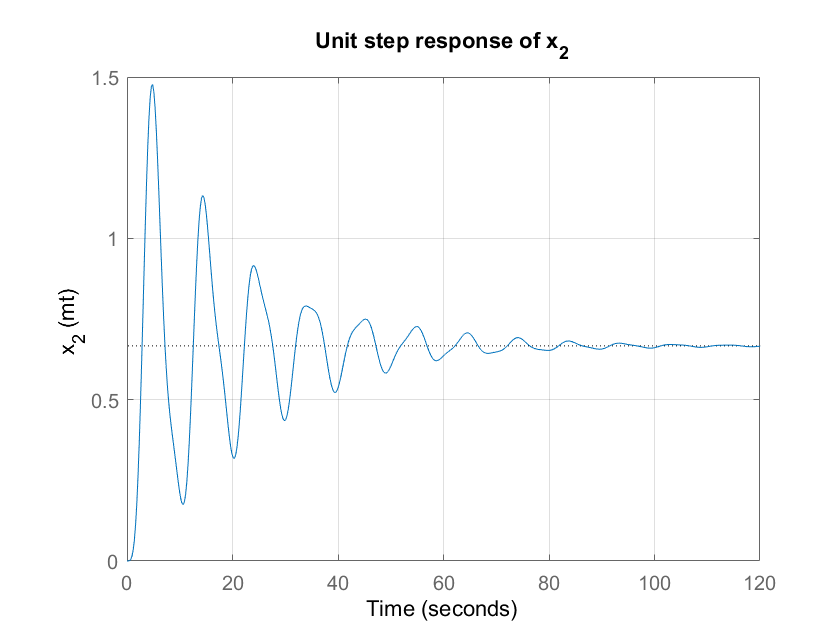


figure
step(tf1)
title("Unit step response of x_2")
grid on
ylabel("x_2 (mt)")

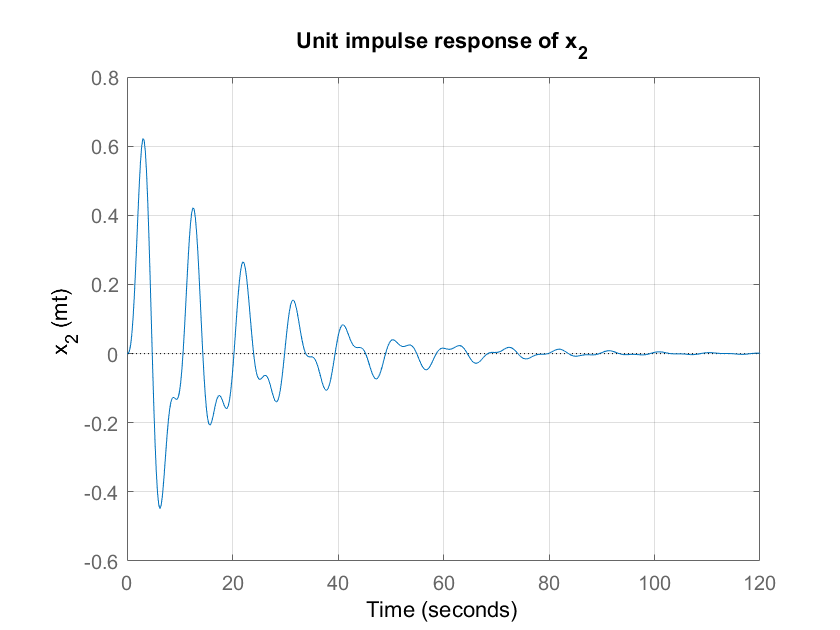


figure
impulse(tf1)
title("Unit impulse response of x_2")
grid on
ylabel("x_2 (mt)")

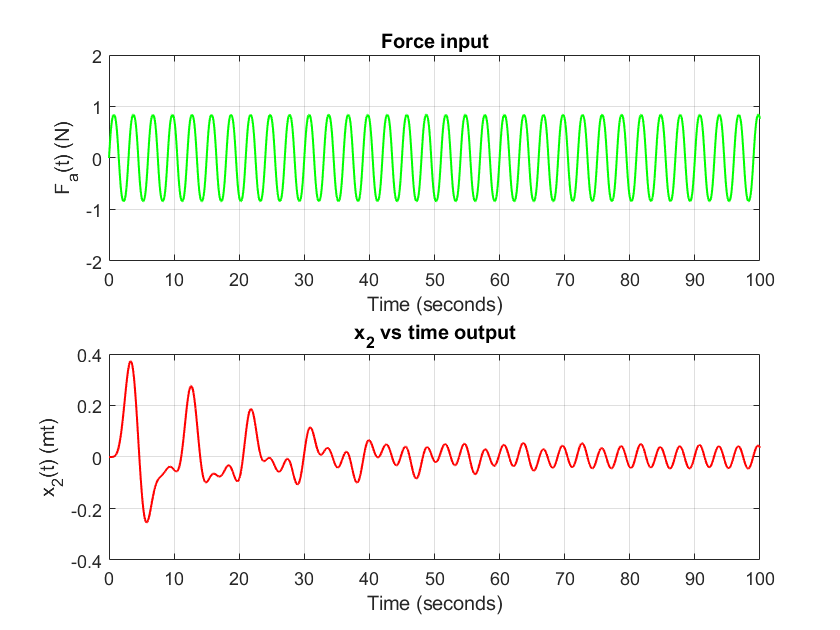


figure
t=0:1e-3:100;
u=sin(sin(2*pi*t/3));
[x2_out,tout]=lsim(tf1,u,t);
subplot(2,1,1)
plot(t,u,"LineWidth",1,"Color","g");
title("Force input");
ylabel("F_a(t) (N)");
xlabel("Time (seconds)");
ylim([-2,2]);
grid on
subplot(2,1,2)
plot(tout,x2_out,"LineWidth",1,"Color","r")
title("x_2 vs time output");
ylabel("x_2(t) (mt)");
xlabel("Time (seconds)");
grid on

Stimulation done in part2.slx

% all the plots are same for the stimulation results as well

% Applying an unit step output

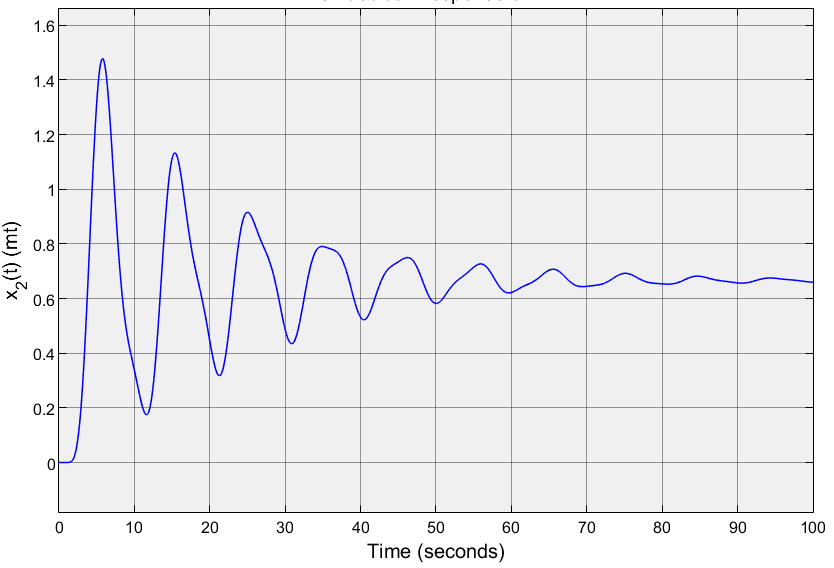

% Applying an unit impulse output

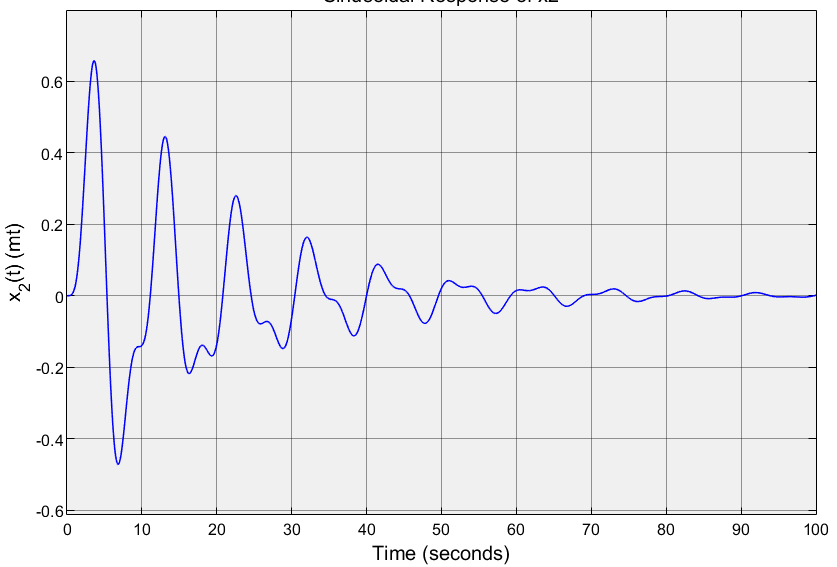

% Applying a sinusoidal output

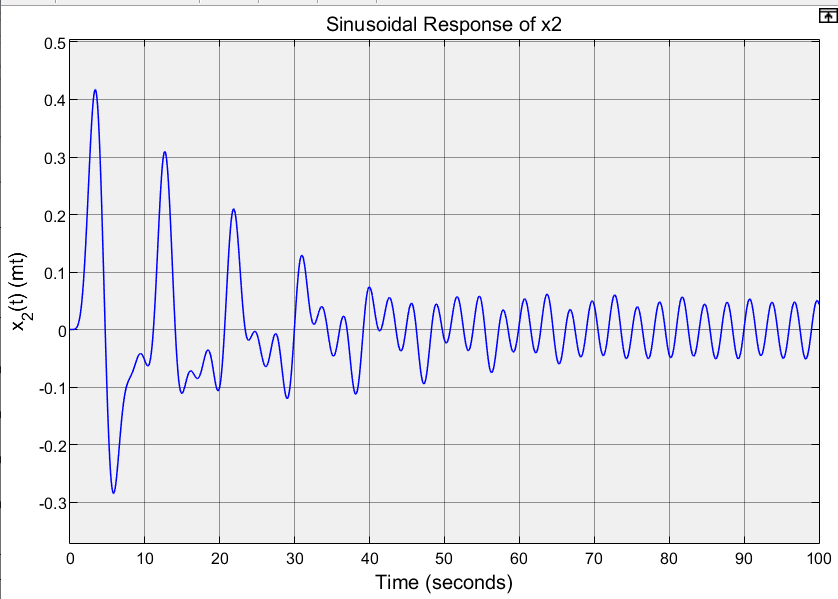

## Q3

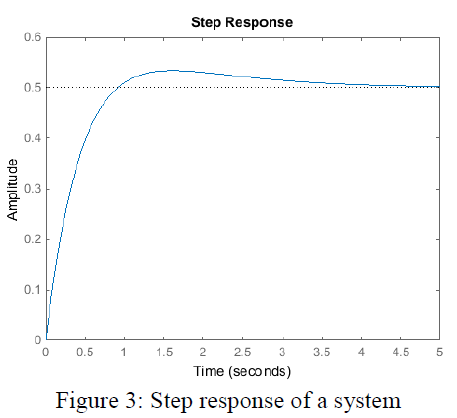

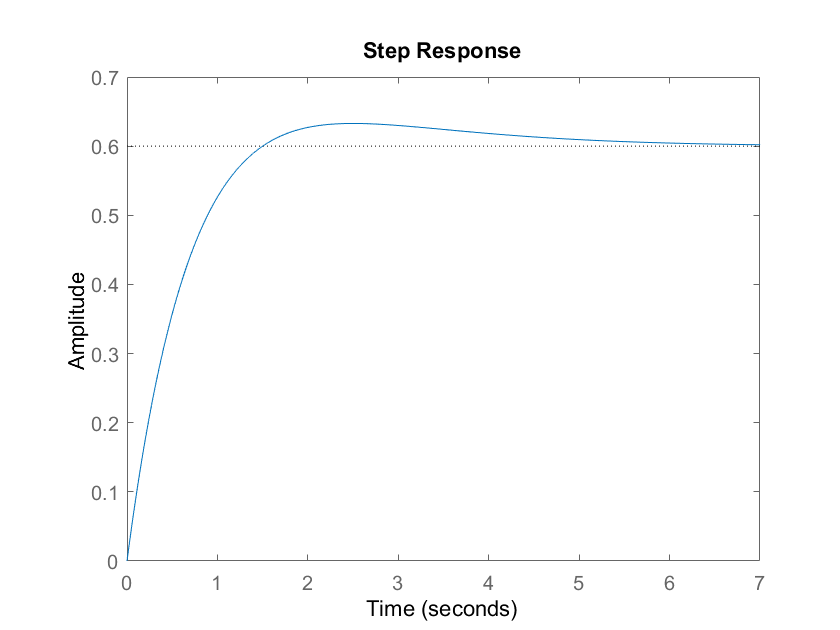

% a
% the response has no oscillatory behaviour but it has an overshoot, thus
% the system is overdamped or critically damped. Overshoot signifies the
% presence of negative zero in system, as it amplifies the initial response.

%example: Critically damped system with poles [-1,-1] and zero -0.6
figure
step([1,0.6],[1,2,1])

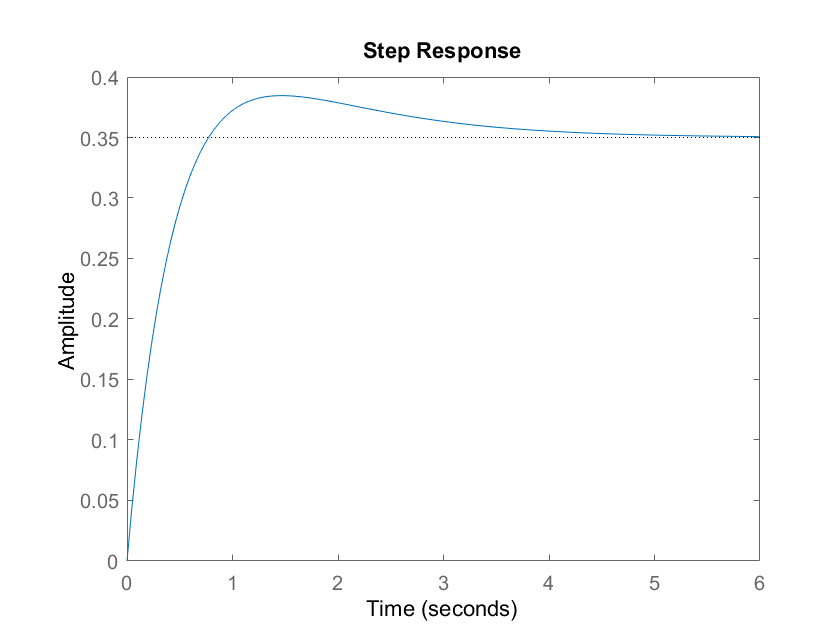

% b
% Yes.
% we observe an overshoot in over-damped 2nd order system, if system has
% negative zero. 

%example: Overdamped with poles [-1,-2] and zero -0.7
figure
step([1,0.7],[1,3,2])

## Q4

% a
% i

figure
tf1=zpk(1,[-1,-1],-1)

tf1 =
 
  - (s-1)
  -------
  (s+1)^2
 
Continuous-time zero/pole/gain model.



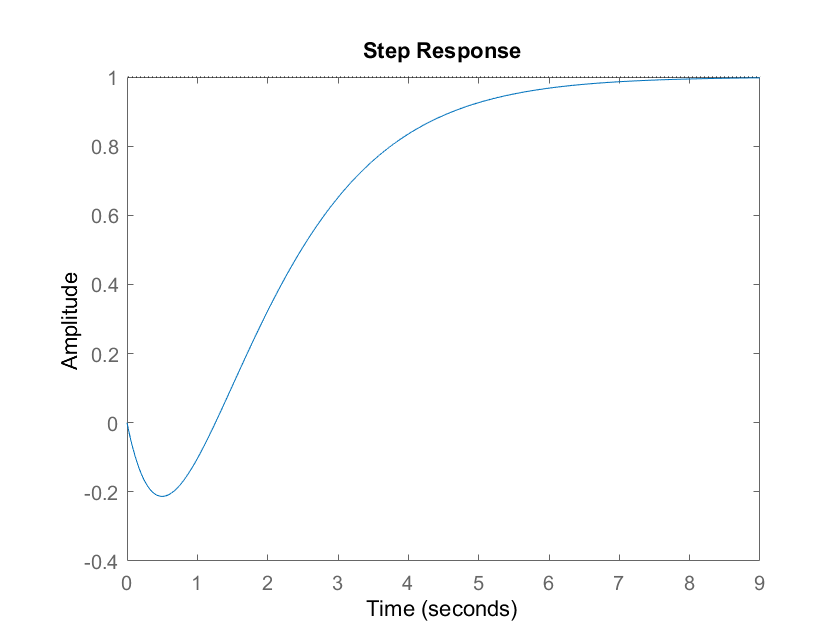

step(tf1)

- Strictly proper

- Initial undershoot

- zero crossing

- no overshoot

- 1 positive zero of $G(s)$

- 1 positive zero of $G(s)-G(\infty)$

- 0 positive zero of $G(s)-G(0)$

% ii

figure
tf2=zpk(1,[-1,-1],1)

tf2 =
 
   (s-1)
  -------
  (s+1)^2
 
Continuous-time zero/pole/gain model.



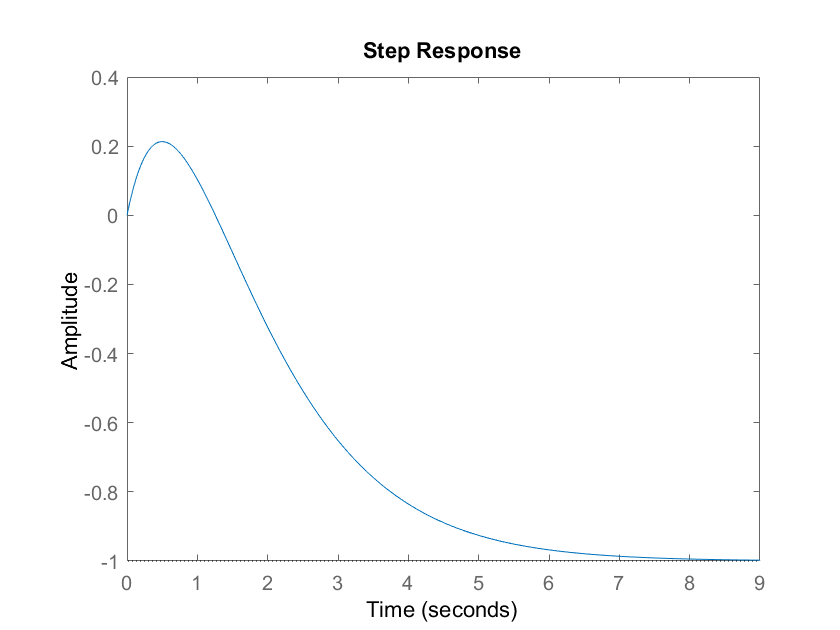


step(tf2)

- Strictly proper

- Initial undershoot

- zero crossing

- no negative overshoot

- 1 positive zero of $G(s)$

- 1 positive zero of $G(s)-G(\infty)$

- 0 positive zero of $G(s)-G(0)$

% iii

figure
tf3=zpk([1,1],[-1,-1],1)

tf3 =
 
  (s-1)^2
  -------
  (s+1)^2
 
Continuous-time zero/pole/gain model.



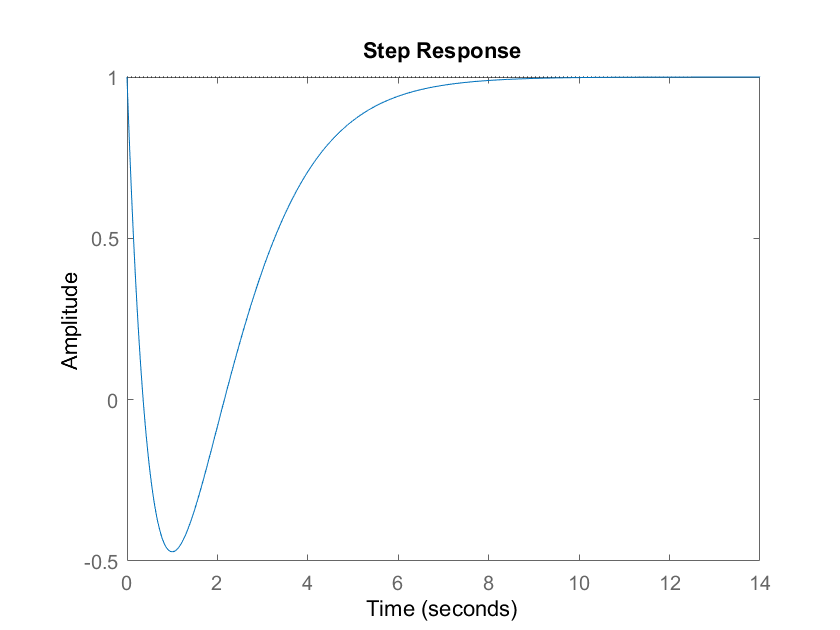

step(tf3)

- Proper

- Initial undershoot

- zero crossing

- no overshoot

- 2 positive zeros of $G(s)$

- 0 positive zero of $G(s)-G(\infty)$

- 0 positive zero of $G(s)-G(0)$

% iv

figure
tf4=tf([0,1,-10,27],[1,9,27,27])

tf4 =
 
      s^2 - 10 s + 27
  -----------------------
  s^3 + 9 s^2 + 27 s + 27
 
Continuous-time transfer function.



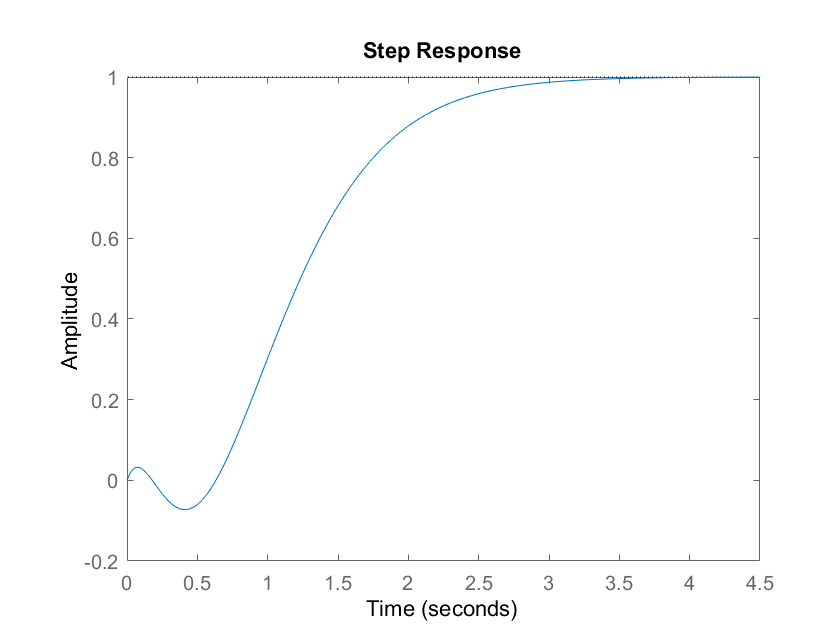

step(tf4)

- Strictly proper

- Initial undershoot

- zero crossing

- no overshoot

- 0 positive zero of $G(s)$, 2 complex zeros

- 0 positive zero of $G(s)-G(\infty)$,2 complex zeros

- 0 positive zero of $G(s)-G(0)$, 2 complex zeros

% v

figure
tf5=tf([2,-1,1],[1,3,3,1])

tf5 =
 
      2 s^2 - s + 1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



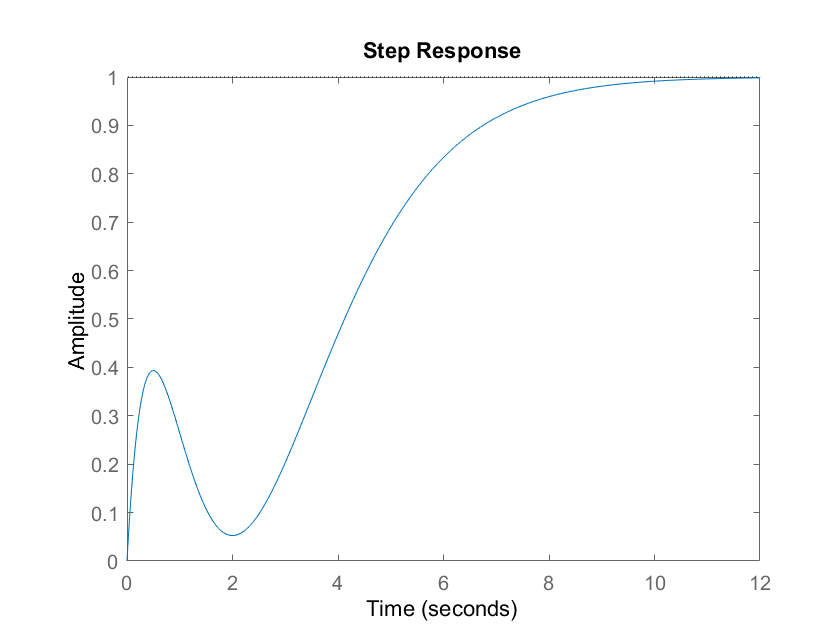


step(tf5)

- Strictly proper

- Initial undershoot

- no zero crossing

- no overshoot

- 0 positive zero of $G(s)$, 2 complex zeros

- 0 positive zero of $G(s)-G(\infty)$, 2 complex zeros

- 0 positive zero of $G(s)-G(0)$, 2 complex zeros

% vi

figure
tf6=tf([1,-1,4],[1,3,3,1])

tf6 =
 
       s^2 - s + 4
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



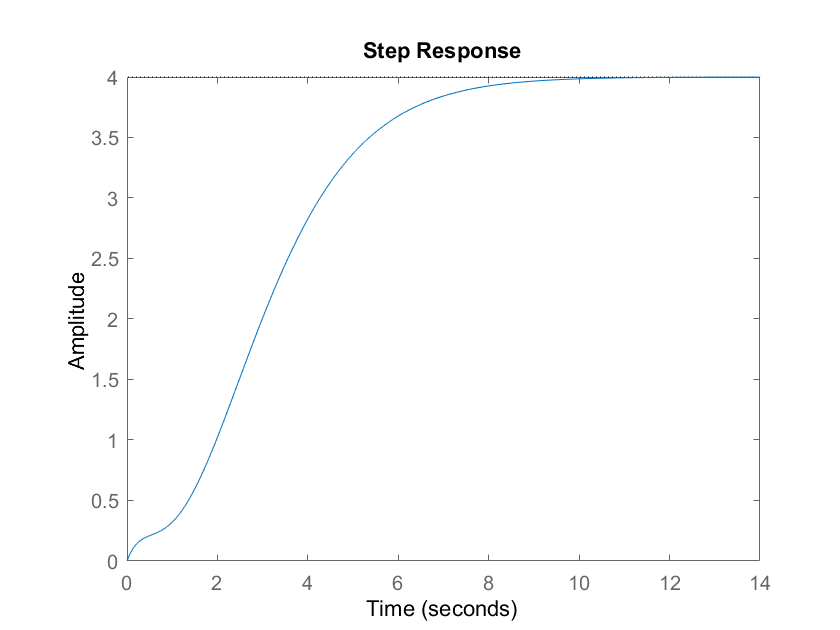

step(tf6)

- Strictly proper

- no initial undershoot

- no zero crossing

- no overshoot

- 0 positive zero of $G(s)$, 2 complex zeros

- 0 positive zero of $G(s)-G(\infty)$, 2 complex zeros

- 0 positive zero of $G(s)-G(0)$, 2 complex zeros

% b
% Yes, a linear dynamical system can give bounded response for unbounded input
% example: for a ramp function we'll get a bounded output

% numerator=s, denominator= (s^2+4s+4)
figure
tf7=tf([1,0],[1,4,4])

tf7 =
 
        s
  -------------
  s^2 + 4 s + 4
 
Continuous-time transfer function.



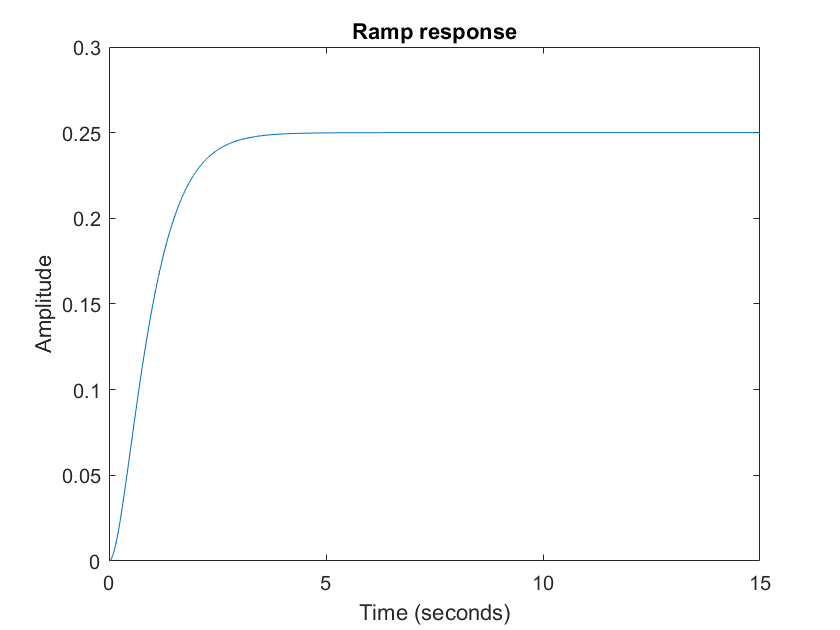

t=0:1e-4:15;
[Y,T]=lsim(tf7,t,t);
plot(T,Y)
title("Ramp response");
ylabel("Amplitude");
xlabel("Time (seconds)");

% unbounded ramp input --> bounded response, from a linear dynamical system

## Q5

% a
% stimulation done in part3.slx
% output response C(s) for 14 different values of delta from 0.2 to 1.5 keeping 
% natural frequency at 16 rad/sec 
% where, R(s) provided by the waveform generator is unit step input at t=0

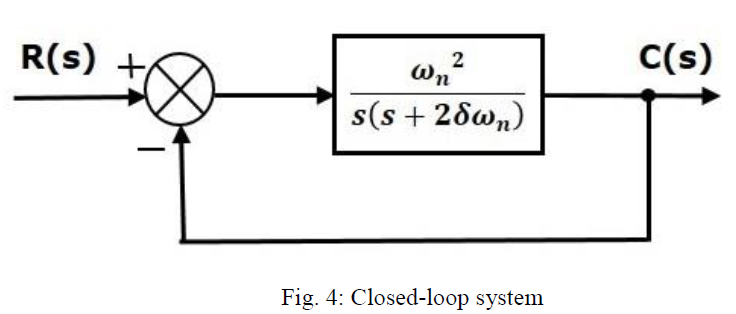

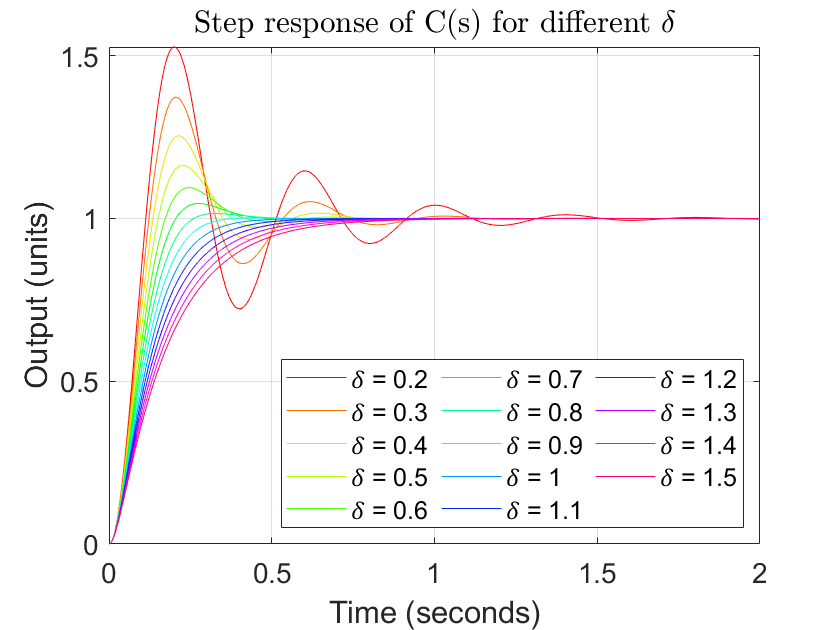

figure;
w=16;
time=0.2:0.1:1.5;
color=hsv(14);
title("Step response of C(s) for different $\delta$",'Interpreter',"latex");
grid on;
xlabel("Time (seconds)");
ylabel("Output (units)");
for i=1:14
    delta=time(i);
    a=sim("part3.slx");
    plot(a.c,'color',color(i,:),'DisplayName',strcat("𝛿 = ",num2str(delta)));
    hold on
end
hold off;
title("Step response of C(s) for different $\delta$",'Interpreter',"latex");
grid on;
xlabel("Time (seconds)");
ylabel("Output (units)");
legend('NumColumns',3, 'Location',"southeast");
set(gca,"FontSize",14);

% With increase in damping ratio (delta), damping frequency of 
% the output decreases. 
% When (delta=1) the system is critically damped, As we increase delta
% system becomes overdamped and takes longer time to reach the final value.

% b
% data provided by TA

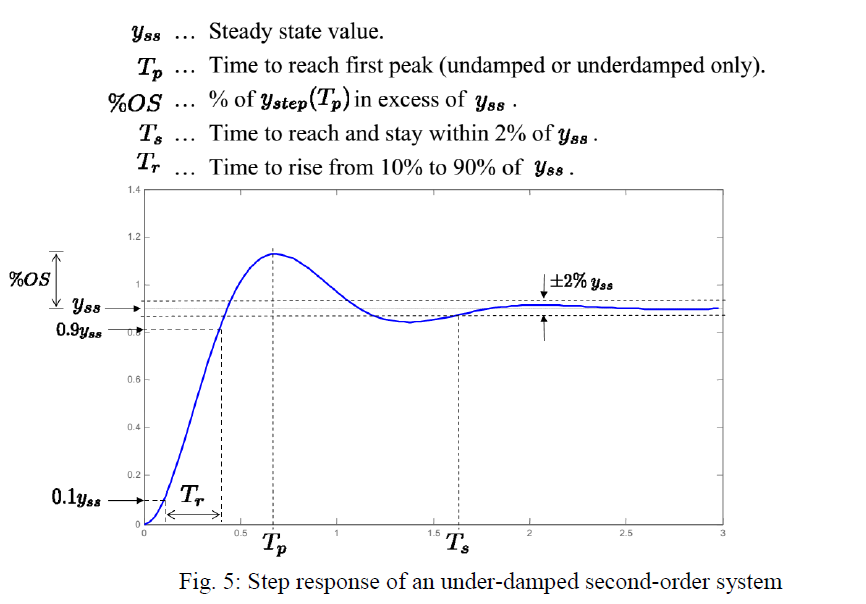

% transfer function

% step signal
t=0:0.01:20;
delta=0.6; %damping ratio
natural_freq=10;

th=atan(sqrt(1-delta^2)/delta);

damping_freq = 8

damping_freq = natural_freq*(sqrt(1-delta^2))

rise_time = 0.2768

rise_time = (pi - th)/damping_freq

peak_time = 0.3927

peak_time = pi/damping_freq

max_peak_overshoot = 0.0948

max_peak_overshoot = exp(-pi*delta/sqrt(1-delta^2))

settling_time = 0.6667

pole = 1.0060

sys =
 
     0.6
  ---------
  z - 1.006
 
Sample time: 0.01 seconds
Discrete-time transfer function.



                                                                        
   Pole       Magnitude     Damping       Frequency      Time Constant  
                                        (rad/seconds)      (seconds)    
                                                                        
  1.01e+00     1.01e+00    -1.00e+00       6.00e-01        -1.67e+00    


settling_time = 4/(delta*natural_freq)